## NN - based DPD

clc;
clear;

### Hyper Parameter

P_DPD = 3; %DPD memory length
num_neuron = 40;

### Load PA input/output data

load('my_dump_file_20bw_15scs_rbs0_rbn_106_cp_20dbm_qpsk.mat');

inDataPA = transpose(dump_pattern.Y_det);
outDataPA = transpose(dump_pattern.X_ref_raw);

num_raw_data = length(inDataPA);
fprintf('num_raw_data: %d\n',num_raw_data);

num_raw_data: 81920


### Split training data and testing data

num_train_data = floor(num_raw_data * 0.5);
num_test_data = num_raw_data - num_train_data;
fprintf("number of training data:%d\n",num_train_data);

number of training data:40960


fprintf("number of testing data:%d\n",num_test_data);

number of testing data:40960


inDataPA_train = inDataPA(1:num_train_data);
inDataPA_test = inDataPA(num_train_data+1:end);
outDataPA_train = outDataPA(1:num_train_data);
outDataPA_test = outDataPA(num_train_data+1:end);

% training: outDataPA needs to do complex gain normalization to let DPD training have unit gain
complex_gain = (conj(inDataPA_train)*transpose(outDataPA_train)) / (conj(outDataPA_train)*transpose(outDataPA_train));
outDataPA_train = outDataPA_train*complex_gain;

inDataPA_train_real = real(inDataPA_train);
inDataPA_train_imag = imag(inDataPA_train);
outDataPA_train_real = real(outDataPA_train);
outDataPA_train_imag = imag(outDataPA_train);

inDataPA_test_real = real(inDataPA_test);
inDataPA_test_imag = imag(inDataPA_test);

### Arrange NN input and NN target

Considering PA's memory effects, arrange NN inputs with delay line.

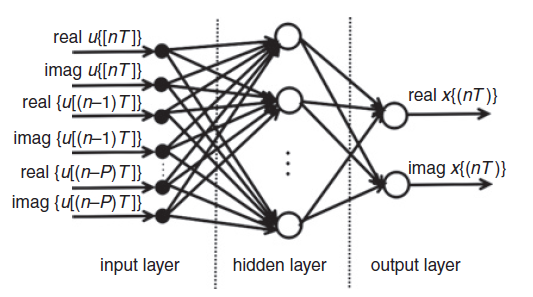

train_input = zeros(num_train_data-P_DPD+1,2*P_DPD);
test_input = zeros(num_test_data-P_DPD+1,2*P_DPD);

for i = (0:P_DPD-1)
    %training input
    train_input(:,i+1) = outDataPA_train_real(P_DPD-i:end-i);
    train_input(:,i+1+P_DPD) = outDataPA_train_imag(P_DPD-i:end-i);
    
    %testing input
    test_input(:,i+1) = inDataPA_test_real(P_DPD-i:end-i);
    test_input(:,i+1+P_DPD) = inDataPA_test_imag(P_DPD-i:end-i);
end
    
train_target = zeros(num_train_data-P_DPD+1,2);   
train_target(:,1) = inDataPA_train_real(P_DPD:end);
train_target(:,2) = inDataPA_train_imag(P_DPD:end);

### Training 

#### using fitnet (special version of feedforwardnet)

% trainFcn = 'trainlm';
% 
% NN = fitnet(num_neuron,trainFcn);
% 
% NN.trainParam.epochs = 2000;  % max epochs
% 
% NN.divideParam.trainRatio = 70/100;
% NN.divideParam.valRatio = 15/100;
% NN.divideParam.testRatio = 15/100;
% 
% % this function requires input and traget's column size must match. tr is
% % training record.
% [NN,tr] = train(NN,transpose(train_input),transpose(train_target));

#### using feedforwardnet (multiple layer)

trainFcn = 'trainlm';
NN = feedforwardnet([num_neuron],trainFcn);
%view(NN);

%NN.divideFcn = 'divideblock'; % 'dividerand'
NN.divideParam.trainRatio = 70/100;
NN.divideParam.valRatio = 30/100;
NN.divideParam.testRatio = 0/100;

% hyper parameter
%NN.trainParam.lr = 0.1;  % learning rate
NN.trainParam.epochs = 1000;  % max epochs
NN.trainParam.max_fail = 100; % Maximum validation failures
NN.trainParam.min_grad = 1e-8; % Minimum performance gradient

% loss function
NN.performFcn = 'mse';

% activation function: 'purelin':linear/'logsig':sigmoid/'tansig'/'poslin':ReLU
NN.layers{1}.transferFcn = 'tansig';
%NN.layers{2}.transferFcn = 'tansig';
%NN.layers{3}.transferFcn = 'purelin';

% this function requires input and traget's column size must match. tr is
% training record.
[NN,tr] = train(NN,transpose(train_input),transpose(train_target));


%calculate DPD output/PA input NMSE(train NMSE)
NN_output_train = NN(transpose(train_input)); 
NN_output_train = transpose(NN_output_train);
NN_output_train = NN_output_train(:,1) + 1j * NN_output_train(:,2);

train_NMSE = 10*log10(sum((abs(inDataPA_train(P_DPD:end)-transpose(NN_output_train))).^2)/sum((abs(inDataPA_train(P_DPD:end))).^2));
fprintf("train_NMSE:%f\n",train_NMSE);

train_NMSE:-42.978027


### Testing

NN_output_test = NN(transpose(test_input)); 
NN_output_test = transpose(NN_output_test);
NN_output_test = NN_output_test(:,1) + 1j * NN_output_test(:,2);

save NN_DPD_output_MATLAB NN_output_test;

fprintf("NN_output_test's length:%d\n",size(NN_output_test,1));

NN_output_test's length:40958


%calculate test_NMSE_indirect (put testing data into DPD when in TRAINING)
complex_gain = (conj(inDataPA_test)*transpose(outDataPA_test)) / (conj(outDataPA_test)*transpose(outDataPA_test));
outDataPA_test = outDataPA_test*complex_gain;

outDataPA_test_real = real(outDataPA_test);
outDataPA_test_imag = imag(outDataPA_test);

test_input = zeros(num_test_data-P_DPD+1,2*P_DPD);
for i = (0:P_DPD-1)    
    %testing input
    test_input(:,i+1) = outDataPA_test_real(P_DPD-i:end-i);
    test_input(:,i+1+P_DPD) = outDataPA_test_imag(P_DPD-i:end-i);
end

NN_output_test = NN(transpose(test_input)); 
NN_output_test = transpose(NN_output_test);
NN_output_test = NN_output_test(:,1) + 1j * NN_output_test(:,2);

test_NMSE_indirect = 10*log10(sum((abs(inDataPA_test(P_DPD:end)-transpose(NN_output_test))).^2)/sum((abs(inDataPA_test(P_DPD:end))).^2));

fprintf("test_NMSE_indirect:%f\n",test_NMSE_indirect);

test_NMSE_indirect:-38.141731
